# GLM

close all;clear;clc;
rng('default')
addpath models\
addpath utils\
load("data/rat_010_07_04_selected.mat")

## Grid Search

Predict **7th** neuron

regulization parameter **alpha **almost useless, might be useful when **xi **is lare and **alpha **is quite small(0~0.1). Use 0 first.

H larger likely be better. xi need not explore a lot.

1/40...Lval=-5575.3707
2/40...Lval=-5491.7498
3/40...Lval=-5489.6767
4/40...Lval=-5489.667
5/40...Lval=-5489.667
6/40...Lval=-5489.667
7/40...Lval=-5489.667
8/40...Lval=-5489.667
9/40...Lval=-5489.667
10/40...Lval=-5489.667
11/40...Lval=-5489.667


12/40:Train Complete...L:-5489.667	...H:1	...xi:0.1	...alpha:0
      Test Complete...L:-5490.8462	...DBR:0.52942


H 1 xi 0.1 DBR 0.52942


1/40...Lval=-5574.8972
2/40...Lval=-5490.6304
3/40...Lval=-5488.7067
4/40...Lval=-5488.6983
5/40...Lval=-5488.6983
6/40...Lval=-5488.6983
7/40...Lval=-5488.6983
8/40...Lval=-5488.6983
9/40...Lval=-5488.6983
10/40...Lval=-5488.6983
11/40...Lval=-5488.6983


12/40:Train Complete...L:-5488.6983	...H:2	...xi:0.1	...alpha:0
      Test Complete...L:-5487.5663	...DBR:0.51879


H 2 xi 0.1 DBR 0.51879


1/40...Lval=-5573.237
2/40...Lval=-5487.6406
3/40...Lval=-5485.6103
4/40...Lval=-5485.6008
5/40...Lval=-5485.6008
6/40...Lval=-5485.6008
7/40...Lval=-5485.6008
8/40...Lval=-5485.6008
9/40...Lval=-5485.6008
10/40...Lval=-5485.6008
11/40...Lval=-5485.6008


12/40:Train Complete...L:-5485.6008	...H:3	...xi:0.1	...alpha:0
      Test Complete...L:-5484.1359	...DBR:0.51917


H 3 xi 0.1 DBR 0.51917


1/40...Lval=-5574.299
2/40...Lval=-5489.4442
3/40...Lval=-5487.7733
4/40...Lval=-5487.7698
5/40...Lval=-5487.7698
6/40...Lval=-5487.7698
7/40...Lval=-5487.7698
8/40...Lval=-5487.7698
9/40...Lval=-5487.7698
10/40...Lval=-5487.7698
11/40...Lval=-5487.7698


12/40:Train Complete...L:-5487.7698	...H:4	...xi:0.1	...alpha:0
      Test Complete...L:-5483.063	...DBR:0.51964


H 4 xi 0.1 DBR 0.51964


1/40...Lval=-5576.6735
2/40...Lval=-5493.5577
3/40...Lval=-5492.433
4/40...Lval=-5492.4388
5/40...Lval=-5492.4388
6/40...Lval=-5492.4388
7/40...Lval=-5492.4388
8/40...Lval=-5492.4388
9/40...Lval=-5492.4388
10/40...Lval=-5492.4388
11/40...Lval=-5492.4388


12/40:Train Complete...L:-5492.4388	...H:5	...xi:0.1	...alpha:0
      Test Complete...L:-5485.65	...DBR:0.52218


H 5 xi 0.1 DBR 0.52218


1/40...Lval=-5575.0809
2/40...Lval=-5492.847
3/40...Lval=-5492.052
4/40...Lval=-5492.0638
5/40...Lval=-5492.0638
6/40...Lval=-5492.0638
7/40...Lval=-5492.0638
8/40...Lval=-5492.0638
9/40...Lval=-5492.0638
10/40...Lval=-5492.0638
11/40...Lval=-5492.0638


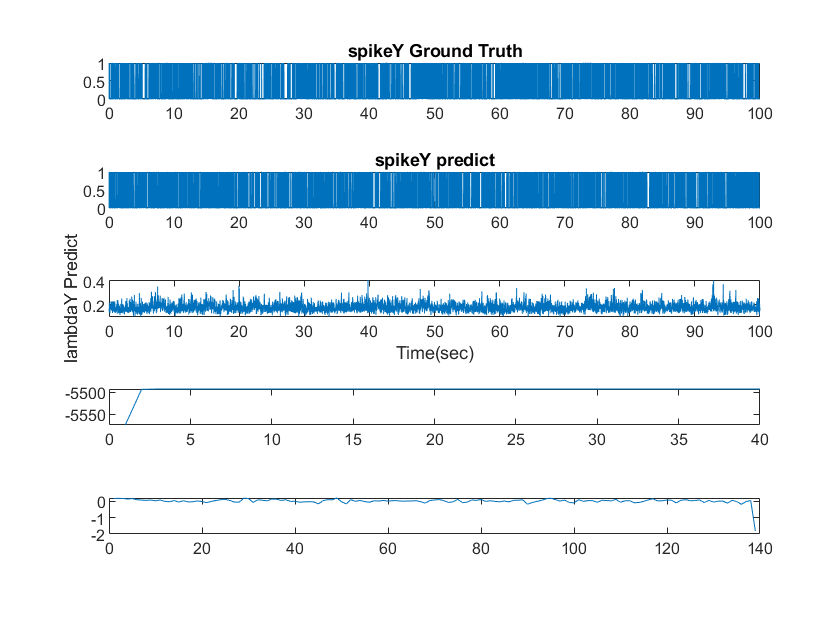

12/40:Train Complete...L:-5492.0638	...H:6	...xi:0.1	...alpha:0
      Test Complete...L:-5489.1951	...DBR:0.50648


H 6 xi 0.1 DBR 0.50648


1/40...Lval=-5575.5662
2/40...Lval=-5494.8683


GLM_explore_H = struct( ...
  "H",{}, "xi",{}, "thres",{}, "iterThres",{}, ...
  "maxIter",{}, "alpha",{}, "M1Idx",{}, ...
  "W",{}, "L",{}, "DBR",{}, "Lval",{}, "LHistory",{} ...
  );
for H=1:10 % Temporal history. Explore within [1:10]
  xi=0.1; % Weights random initial range parameter
  alpha=0; % Regulization parameter
  thres = 1e-3; % stop error tolerance
  iterThres = 7; % stop after error over threshold $ times
  maxIter = 40; % max iteration num, over needs re-initial
  M1Idx = 1; % select M1 neuron
  splitFun = @(history)splitData(mPFCspike,M1spike(:,M1Idx),history); % choose splitData function as first Order
  verbose = 0;
  [W, L, DBR, Lval, LHistory] = runGLM(H, xi, thres, iterThres, maxIter, alpha, splitFun, verbose);
  GLM_explore_H(H) = struct( ...
    "H",H, "xi",xi, "thres",thres, "iterThres",iterThres, ...
    "maxIter",maxIter, "alpha",alpha, "M1Idx",M1Idx, ...
    "W",W, "L",L, "DBR",DBR, "Lval",Lval, "LHistory",LHistory ...
    );
  disp(['H ', num2str(H), ' xi ', num2str(xi), ' DBR ', num2str(DBR)])
end

save("results\GLM_explore_H.mat", "GLM_explore_H")

## Result analyze

### DBR-history

DBR = zeros(1,10);
for i=1:10
  DBR(i) = GLM_explore_H(i).DBR;
end
figure(1)
plot(10:10:100, DBR)
xlabel("Length of mPFC history(msec)")
xlim([10 100])
ylabel("7th neuron DBR")
title("DBR-history")

### firing rate, cc kernel size analyze

Take history=9 for firing rate cc-kernel size analyze, kernel size changes from 10~1000(*10msec)

W = GLM_explore_H(5).W;
H = GLM_explore_H(5).H;
M1Idx = GLM_explore_H(5).M1Idx;
[~,~,testLen,~,~,testX,~,~,testY] = splitData(mPFCspike,M1spike(:,M1Idx),H);
testLambdaYpre = GLMmodel(testX, W);
ccList = zeros(1, 1000/10);
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(testLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ccList(kernelSize/10) = cc(2);
end

take kernel size=200(2s) for plot

smoothedLambda    = gaussianSmooth(testY, 100);
smoothedLambdaPre = gaussianSmooth(testLambdaYpre, 100);
figure(2)
subplot(3,1,1)
area(0.01:0.01:120, testY(1:12000))
xlabel("time(sec)")
set(gca, 'ytick', [])
set(gca, 'box', 'off')
subplot(3,1,2)
plot(0.01:0.01:120, smoothedLambda(1:12000))
hold on
plot(0.01:0.01:120, smoothedLambdaPre(1:12000))
hold off
xlabel("time(sec)")
ylabel("Firing rate")
legend("Actual M1 spike", "GLM")
subplot(3,1,3)
plot(0.1:0.1:10, ccList)
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size(History=90msec)")